Console preparation

clc;
close all; 
warning('off', 'all');

Import the data for the step response of the fan

%fan step from 0% duty cycle to 60% dutycycle
open('Figures\01122025_stepresponse_rpm.fig'); 
a = get(gca,'Children');  
obj_r = a(2);  
x_step_response = obj_r.XData;
y_step_response = obj_r.YData; 
close(gcf);

% from at a low point to hovering in a higher point duty cycle from 8.75%
% to 9.35%
open('Figures\01122025_hover_ramp_rpm.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_rpm_ramp = obj_r_alpha2.XData;
y_rpm_ramp = obj_r_alpha2.YData; 
close(gcf);

open('Figures\01122025_hover_ramp_height.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_height_ramp = obj_r_alpha2.XData;
y_height_ramp = obj_r_alpha2.YData; 
close(gcf);

# Variable definitions

g = 9.81; % [m/s^2] 
rotations_at_ss = 4200; % [rpm]

# Linear regression of duty_cycle/rpm

duty_cycle =    [0      5       7.5     10      20      40      50]; % [%]
rpm     =       [3070   3790    4050    4325    5450    7150    8000];% [rpm]

A = [duty_cycle(:), ones(length(duty_cycle), 1)];
b = rpm(:);
x = A \ b;
negative_rpm_0 = x(2);
rpm_0 = -negative_rpm_0;
k_omega = x(1) % [rpm/%]

k_omega = 96.2950

u_0 = rpm_0 / k_omega % [%]

u_0 = -34.2340

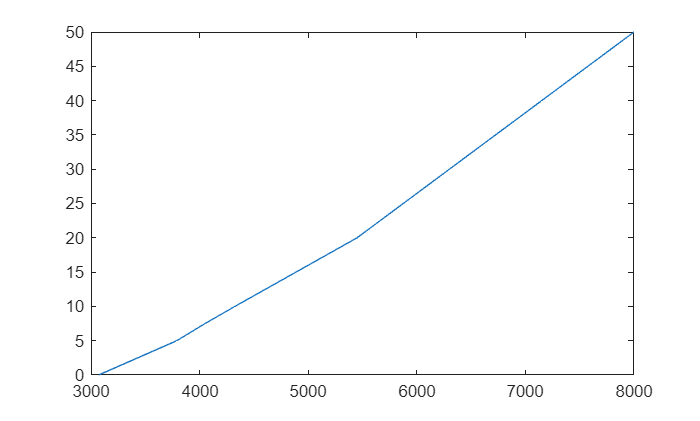

plot(rpm,duty_cycle); 

# Step response of the real System

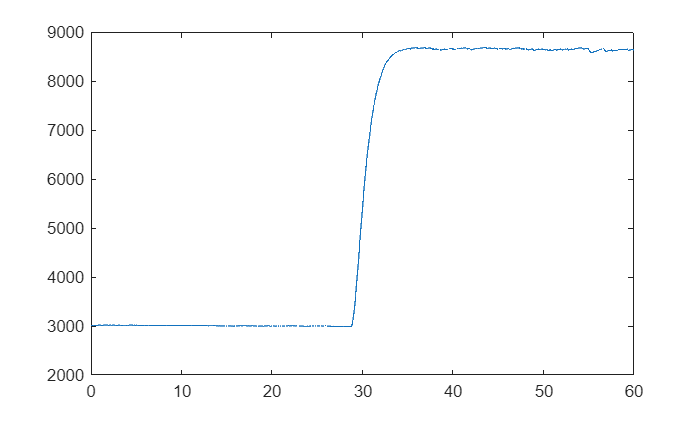

time_limit_sr = max(x_step_response) - 60; 
idx_sr = x_step_response >= time_limit_sr;
x_step_response = x_step_response(idx_sr);
y_step_response = y_step_response(idx_sr);
t_r = x_step_response(:);
Ts_r = mean(diff(t_r));
y_rotations = y_step_response;
plot(t_r,y_step_response);

tau_omega = 29.985 - 28.73 % [s]

tau_omega = 1.2550

# Transition from one floating point to another floating point to get zdot and rpm 

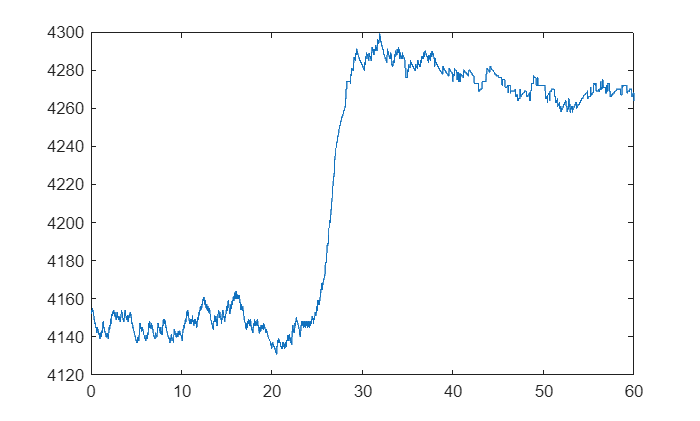

time_limit_cw = max(x_rpm_ramp)-60; 
idx_cw = x_rpm_ramp >= time_limit_cw;
x_rpm_ramp = x_rpm_ramp(idx_cw);
y_rpm_ramp = y_rpm_ramp(idx_cw);
t_cw = x_rpm_ramp(:);        
Ts_cw = mean(diff(t_cw));    
plot(t_cw,y_rpm_ramp);

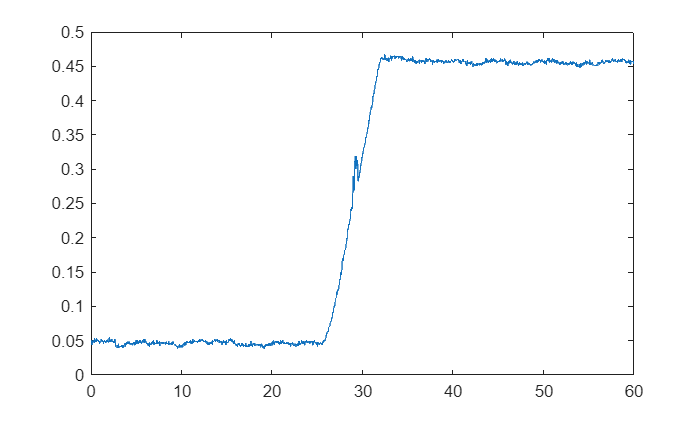

time_limit_height = max(x_height_ramp) - 60;
idx_height = x_height_ramp >= time_limit_height;
x_height_ramp = x_height_ramp(idx_height);
y_height_ramp = y_height_ramp(idx_height);
t_height = x_height_ramp(:);
Ts_height = mean(diff(t_height));
plot(t_height,y_height_ramp);

avg_rpm_constant = (4285+4153)/2 % [rpm]

avg_rpm_constant = 4219

# Calculation of the coefficients

alpha1 = sqrt(g)/rotations_at_ss; 
z_dot = (0.453-0.05)/(31.825-25.875) % [m/s]

z_dot = 0.0677

alpha2 = (alpha1 * avg_rpm_constant - sqrt(g))/z_dot; 
alpha3 = g; % [m/s^2]
u0 = 0; 
a  = 4178.75; % [rpm]
fprintf(['alpha1 = %g;\n', ...
         'alpha2 = %g;\n', ...
         'alpha3 = %g;\n', ...\n', ...
         'tau_omega = %g; \n', ...
         'u_0 = %g; \n', ...
         'k_omega = %g;\n'], ...
         alpha1, alpha2, alpha3, tau_omega,u_0, k_omega);

alpha1 = 0.000745736;
alpha2 = 0.209195;
alpha3 = 9.81;
tau_omega = 1.255; 
u_0 = -34.234; 
k_omega = 96.295;


omega_bar = sqrt(alpha3)/alpha1;

A = [ 0, 1, 0;
      0, -2*alpha1*alpha2*omega_bar,  2*alpha1^2*omega_bar;
      0, 0, -1/tau_omega ];

B = [0; 0; k_omega/tau_omega];

C = [1 0 0];

D = 0;

state_space_sys = ss(A,B,C,D);

G_lin = tf(state_space_sys)


G_lin =
 
           0.3584
  -------------------------
  s^3 + 2.107 s^2 + 1.044 s
 
Continuous-time transfer function.



%% Controller
% Define the PID controller
Kp = 1; % Proportional gain
Ki = 0.1; % Integral gain
Kd = 0.01; % Derivative gain
C_pid = pid(Kp, Ki, Kd);

% Closed-loop system
sys_cl = feedback(C_pid * G_lin, 1);
PID = pidTuner(G_lin,'PID');

% Tuned parameters
Kp_tuned = Tuned_PID.Kp;

Unable to resolve the name 'Tuned_PID.Kp'.

Ki_tuned = Tuned_PID.Ki;
Kd_tuned = Tuned_PID.Kd;